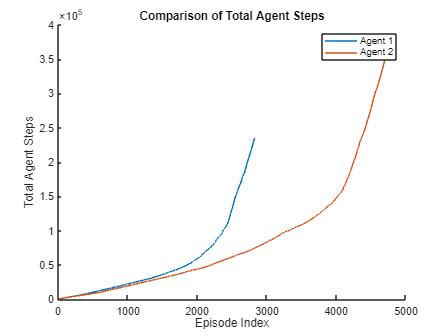

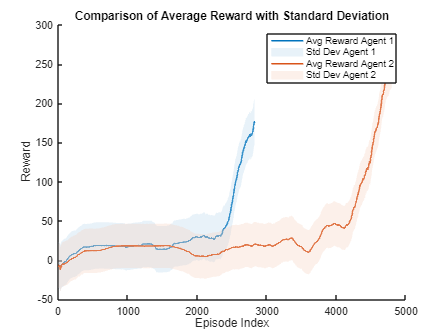

function compareAgentTraining(varargin)
    % compareAgentTraining Compare the training results of multiple agents.
    % Usage:
    % compareAgentTraining('agent1_trainingStats.mat', 'agent2_trainingStats.mat', ...)
    
    numAgents = nargin;
    
    if numAgents < 2
        error('You must provide at least two agents for comparison.');
    end
    % Predefined set of colors for the agents
    predefinedColors = [
        0.00, 0.45, 0.74;  % Blue
        0.85, 0.33, 0.10;  % Red
        0.93, 0.69, 0.13;  % Yellow
        0.49, 0.18, 0.56;  % Purple
        0.47, 0.67, 0.19;  % Green
        0.30, 0.75, 0.93;  % Cyan
        0.64, 0.08, 0.18   % Dark Red
    ];
    
    % Ensure enough colors are available
    if numAgents > size(predefinedColors, 1)
        error('Not enough predefined colors for the number of agents.');
    end
    % Initialize cell arrays to hold data for each agent
    episodeIndex = cell(1, numAgents);

    episodeReward = cell(1, numAgents);
    episodeSteps = cell(1, numAgents);
    averageReward = cell(1, numAgents);
    totalAgentSteps = cell(1, numAgents);
    averageSteps = cell(1, numAgents);
    episodeQ0 = cell(1, numAgents);
    
    % Load data from each .mat file
    for i = 1:numAgents
        data = load(varargin{i}).trainingStats;
        
        % Assuming that the data structure in each file contains the fields mentioned
        episodeIndex{i} = data.EpisodeIndex;
        episodeReward{i} = data.EpisodeReward;
        episodeSteps{i} = data.EpisodeSteps;
        averageReward{i} = data.AverageReward;
        totalAgentSteps{i} = data.TotalAgentSteps;
        averageSteps{i} = data.AverageSteps;
        episodeQ0{i} = data.EpisodeQ0;
    end
    
    % Plot the Episode Rewards comparison
    % figure;
    % hold on;
    % for i = 1:numAgents
    %     plot(episodeIndex{i}, episodeReward{i}, 'DisplayName', sprintf('Agent %d', i));
    % end
    % xlabel('Episode Index');
    % ylabel('Episode Reward');
    % title('Comparison of Episode Rewards');
    % legend show;
    % hold off;
    
    % Plot the Average Reward comparison
    % figure;
    % hold on;
    % for i = 1:numAgents
    %     plot(episodeIndex{i}, averageReward{i}, 'DisplayName', sprintf('Agent %d', i));
    % end
    % xlabel('Episode Index');
    % ylabel('Average Reward');
    % title('Comparison of Average Rewards');
    % legend show;
    % hold off;
    
    % Plot the Episode Steps comparison
    % figure;
    % hold on;
    % for i = 1:numAgents
    %     plot(episodeIndex{i}, episodeSteps{i}, 'DisplayName', sprintf('Agent %d', i));
    % end
    % xlabel('Episode Index');
    % ylabel('Episode Steps');
    % title('Comparison of Episode Steps');
    % legend show;
    % hold off;
    
    % Plot the Total Agent Steps comparison
    figure;
    hold on;
    for i = 1:numAgents
        plot(episodeIndex{i}, totalAgentSteps{i}, 'DisplayName', sprintf('Agent %d', i));
    end
    xlabel('Episode Index');
    ylabel('Total Agent Steps');
    title('Comparison of Total Agent Steps');
    legend show;
    hold off;
    
    % Plot the Average Steps comparison
    % figure;
    % hold on;
    % for i = 1:numAgents
    %     plot(episodeIndex{i}, averageSteps{i}, 'DisplayName', sprintf('Agent %d', i));
    % end
    % xlabel('Episode Index');
    % ylabel('Average Steps');
    % title('Comparison of Average Steps');
    % legend show;
    % hold off;
    
    % Plot the Episode Q0 comparison
    % figure;
    % hold on;
    % for i = 1:numAgents
    %     plot(episodeIndex{i}, episodeQ0{i}, 'DisplayName', sprintf('Agent %d', i));
    % end
    % xlabel('Episode Index');
    % ylabel('Episode Q0');
    % title('Comparison of Episode Q0');
    % legend show;
    % hold off;

    % Plot the Average Reward with Standard Deviation (Episode Reward) comparison
    figure;
    hold on;
    for i = 1:numAgents
        % Calculate the standard deviation around the average reward
        stdDev = std(episodeReward{i} - averageReward{i});
        
        % Get the color for this agent
        agentColor = predefinedColors(i, :);
        lightColor = agentColor + (1 - agentColor) * 0.7;  % Lighter version of the color
        
        % Plot the average reward
        plot(episodeIndex{i}, averageReward{i}, 'Color', agentColor, 'LineWidth', 1.5, 'DisplayName', sprintf('Avg Reward Agent %d', i));
        
        % Fill the area around the average reward to show standard deviation
        fill([episodeIndex{i}; flipud(episodeIndex{i})], ...
             [averageReward{i} + stdDev; flipud(averageReward{i} - stdDev)], ...
             lightColor, 'FaceAlpha', 0.3, 'EdgeColor', 'none', 'DisplayName', sprintf('Std Dev Agent %d', i));
    end
    xlabel('Episode Index');
    ylabel('Reward');
    title('Comparison of Average Reward with Standard Deviation');
    legend show;
    hold off;
end

compareAgentTraining('trainingStats_cont.mat','trainingStats.mat');
    